## Problem 3.

다음과 같은 1차 시스템을 고려하자. 


$$\dot{y} = ay + bu$$


여기서 시스템 파라미터의 참 값은 $a = -2,$ $b = 1$이나, 이 값은 정확히 알지 못한다고 가정하자. 시스템 파라미터의 추정 초기값으로 $\hat{a}_0 = 1,$ $\hat{b}_0 = 2$로 설정하자.

일차 시스템을 제어하기 위하여 Self-tuning 기법을 바탕으로 제어기를 설계하고자 한다. 이때 고려하는 제어기의 구조는 다음과 같다. 


$$u = k_1 r - k_2 y$$


### a)

시스템 파라미터의 초기 값 ($\hat{a}_0 = 1,$ $\hat{b}_0 = 2$)을 고려하여 단위계단 입력 $r(t)$에 대한 추정오차가 $0$이 되고,  closed-loop pole $p = -2$ 가 되도록 하는 $k_1,$ $k_2$의 값을 구하여라

***sol)***

시스템 파라미터 초기 값을 고려한 $\dot{y} = \hat{a}_0 y + \hat{b}_0 u$의 Laplace transform은 $y(0) = 0$ 가정에서 $sY_m(s) = \hat{a}_0 Y_m(s) + \hat{b}_0 U(s)$이다. 제어기 $u = k_1r - k_2y$의 Laplace transform은 $U(s) = k_1 R(s) - k_2 Y_m(s)$이다. Closed-loop transfer function을 구해보면,


$$sY_m(s) = \hat{a}_0 Y_m(s) + \hat{b}_0 U(s) = \hat{a}_0 Y_m(s) + \hat{b}_0 (k_1 R(s) - k_2 Y_m(s))$$



$$(s - \hat{a}_0 + \hat{b}_0 k_2)Y_m(s) = \hat{b}_0 k_1 R(s)$$


$\frac{Y_m(s)}{R(s)} = \frac{\hat{b}_0 k_1}{s - \hat{a}_0 + \hat{b}_0 k_2}$이다. Pole이 $-2$가 되기 위해선 $- \hat{a}_0 + \hat{b}_0 k_2 = 2$이다. 따라서 $k_2 = 3/2$이다. Step input $R(s)$에 대해서 추정오차가 $0$이 되기 위해선 $\lim_{s\rightarrow 0}(R(s) - Y_m(s))s = \lim_{s\rightarrow 0}\left(1 - \frac{\hat{b}_0 k_1}{s - \hat{a}_0 + \hat{b}_0k_2}\right) = 0$을 만족하는 $k_1$을 계산해야 한다.


$$1 - \frac{2k_1}{-1+2\times 3/2} = 1- k_1 = 0$$


즉, unit step input $r(t)$에 대한 오차가 $0$이 되고, closed-loop pole이 $-2$가 되도록 하는 $k_1$, $k_2$의 값은 $1$, $3/2$이다.

### b)

a)에서 설정한 ($k_1$, $k_2$)를 바탕으로 self-tuning 기법을 적용해 parameter 적응 규칙을 설계해라

***sol)***

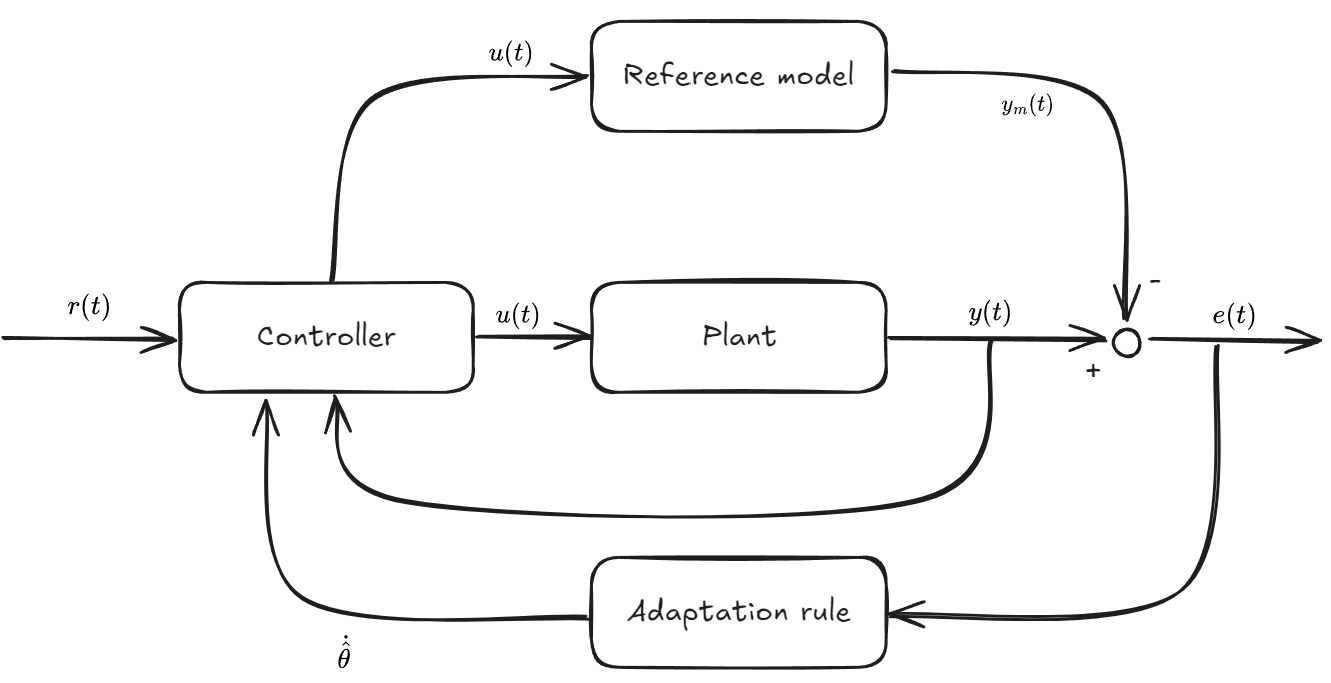

Reference input $r(t)$ 앞에 sampler가 존재하고, plant의 output, reference model의 output을 측정하는 곳에 sampler가 있다고 가정하며, sampling time은 $T=0.1$로 설정한다. 앞선 가정을 통해 Z-transformation과 Laplace transform table을 이용해서 a)의 전달함수를 discrete transfer function의 형태로 만들 수 있다. Zero-order holder의 가정 하에서 controller-plant의 discrete transfer function은

$Z\left\{(1 - e^{-Ts})\frac{Y_p(s)}{sR(s)}\right\} = (1-z^{-1})Z\left\{\frac{bk_1}{s(s - a + bk_2)}\right\} = \left(\frac{z-1}{z}\right)\left(\frac{z(1 - e^{(a - bk_2)T}}{(z-1)(z-e^{(a - bk_2)T})}\right)\left(\frac{bk_1}{-a + bk_2}\right)$와 같다.

수치를 대입해서 풀어보면, $\frac{Y_m(z)}{R(z)}=\frac{1 - exp(0.1(1-2k_2))}{z - exp(0.1(1-2k_2))}\frac{2k_1}{1 - k_2}$, $y_m(k + 1) = exp(0.1(1-2k_2))y_m(k) + (1 - exp(0.1(1-2k_2)))r(k)\frac{2k_1}{1 + 2 k_2}$이다. 이는 실제 모델도 똑같이 적용할 수 있으므로 controller-plant의 discrete transfer function은 $y_p(k + 1) = exp(0.1(-2-k_2))y_p(k) + (1 - exp(0.1(-2-k_2)))r(k)\frac{k_1}{2 + k_2}$이다.

Reference input을 가하는 한 sample의 error를 바탕으로 다음 sample의 controller gain $k_1$, $k_2$를 업데이트 해야하므로 그 관계는 $k_1(k + 1) = k_1(k+1) + T\left(-\gamma e(k) \frac{\partial e}{\partial k_1}(k+1)\right)$, $k_2(k + 1) = k_2(k) + T\left(-\gamma e(k+1) \frac{\partial e}{\partial k_2}(k+1)\right)$와 같다.

이때, $e(k + 1) = y_p(k + 1) - y_m(k + 1)$이므로, $y_p(k + 1) - y_m(k + 1) = e^{a - bk_2}y_b(k) + (1 - e^{a-bk_2})r(k)\frac{bk_1}{-a + bk_2} - e^{\hat{a}_0 - \hat{b}_0k_2}y_b(k) - (1 - e^{\hat{a}_0-\hat{b}_0k_2})r(k)\frac{\hat{b}_0k_1}{-\hat{a}_0 + \hat{b}_0k_2}$이다.

$e^{a - bk_2} \approx e^{\hat{a}_0 - \hat{b}_0k_2}$ 가정 하에서

 이를 a)에 적용하여 unit step input에 대해 self tuning controller를 설계해 그 반응을 나타내 보겠다.

plant_output_y = 0;         % Plant output
prev_plant_output_y = 0;    % Previous plant output
model_output_y = 0;         % Reference model output
prev_model_output_y = 0;    % Previous model output
ref_input_r = 1;            % Unit step input
k1 = 1;                     % Initial gain k1
grad_k1 = 0;                % Update factor for gain k1
k2 = 3/2;                   % Initial gain k2
grad_k2 = 0;                % Update factor for gain k2


